MATLAB In-Class exercises 1

Lecturer: Mokshin V.V.

Student: Galimov M.D.

Group № 4167

Kazan, 2019 

Exercise 1. Write a function that calculates the correlation between two input vectors. Use only basic MATLAB functions (e.g. mean, std, etc.).

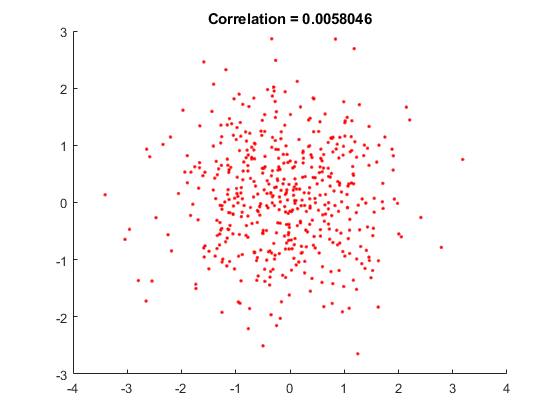

N=500;
figure;
hold on;
x=randn(1, N);
y=randn(1, N);
h = scatter(x, y, 'r.');
CORR = corrcoef(x, y);
title('Correlation = ' + string(CORR(1, 2)));

Exercise 2. Conduct Monte Carlo simulations in which samples are drawn from a Gaussian distribution with mean 10 and standard deviation 2. For each of various sample sizes (n = 2, 5, 10, 20, 50, 100, 200, 500, 1000), draw 1,000 random samples, compute the mean of each sample, and quantify the spread in the results by computing standard deviation. Then make a line plot that shows the relationship between sample size (x-axis) and the uncertainty (spread) of the mean (y-axis). On the same figure, draw a line that shows the theoretical expectation.

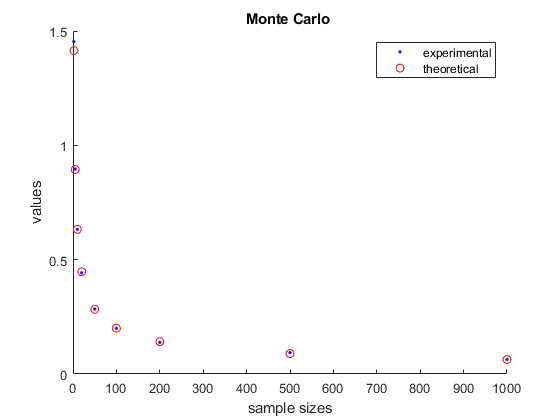

samplesizes = [2 5 10 20 50 100 200 500 1000];
standard_deviations = zeros(1,length(samplesizes));
SEM = zeros(1,length(samplesizes));
for i = 1:length(samplesizes)
    samplesize = samplesizes(i);
    temp_means = zeros(1,1000);
    for j = 1:1000
        sample = normrnd(10,2, [samplesize, 1]);
        temp_means(j) = mean(sample);
    end
    standard_deviations(i)=std(temp_means);
    SEM(i) = 2/sqrt(samplesize);
end
figure;
hold on;
plot(samplesizes, standard_deviations, 'b.');
plot(samplesizes, SEM, 'ro');
title('Monte Carlo ');
xlabel('sample sizes');
ylabel('values');
legend('experimental','theoretical');

Exercise 3. Write a function that accepts an input vector and returns a new vector representing a bootstrap sample drawn from the original vector

get_bootstrap_sample.m

x=randn(1, 5);
y = get_bootstrap_sample(x);
disp(y);

    1.5106   -0.3232   -0.0936   -0.0936   -0.3232



Exercise 4. Modify the function in Exercise 3 to accept another input specifying the number of bootstrap samples to draw. Then have the function return a 2D matrix with different bootstrap samples in the columns of the matrix. Avoid the use of for-loops in this function so that the function is fast.

get_bootstrap_samples.m

x=randn(1, 5);
y = get_bootstrap_samples(x, 5);
disp(x);

    0.1338    1.4202    0.3078    1.3592    0.0520



disp(y);

    0.1338    1.3592    0.0520    0.0520    0.1338
    0.1338    1.3592    0.1338    0.3078    0.0520
    1.4202    1.4202    0.3078    0.1338    0.3078
    0.3078    1.4202    1.4202    0.3078    0.0520
    1.4202    0.0520    0.0520    1.4202    1.4202



Exercise 5. Generate some correlated data (two variables). Visualize the data using a scatter plot. Then compute a 2D histogram of these data and visualize the histogram as an image. Compute the marginal distribution of the data (showing the distribution of the data on each variable separately) and then compute the joint distribution that we would expect to observe if the variables were independent. Visualize this distribution as an image.

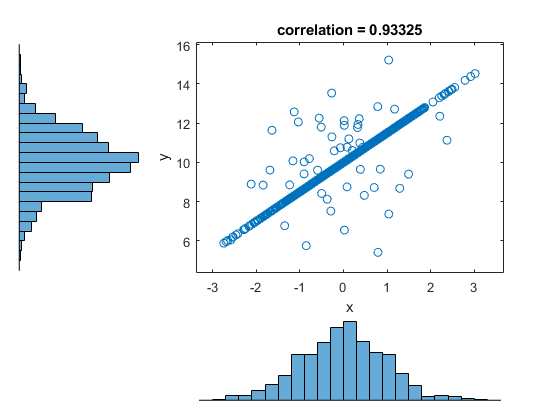

%generate random sample
x = randn(1, 900);
%get sample correlated with initial sample
y = x*1.5 + 10;
y_noised = y;
%generate normal(10, 2) noise
indexes = randi(900, 1, 50);
independent = normrnd(10, 2, [1, 900]);
%add noise
y_noised(indexes) = independent(indexes);
%find correlation coefficient
corr = corrcoef(x, y_noised);
figure;
hold on;
%2D histogram 
h1 = scatterhist(x, y_noised);
title('correlation = ' + string(corr(1, 2)));
xlabel('x');
ylabel('y');

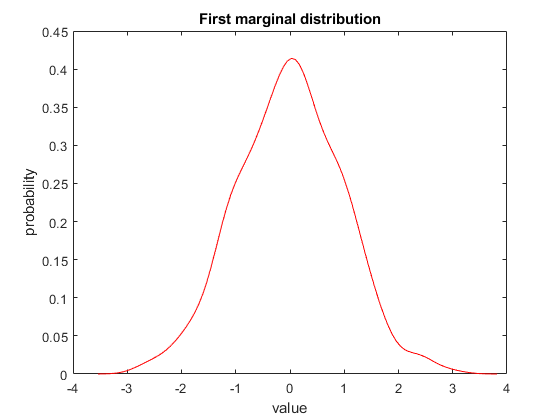

figure;
%plot marginal distribution of first sample
[f,xi] = ksdensity(x);
plot(xi,f, 'r-');
title('First marginal distribution');
xlabel('value');
ylabel('probability');

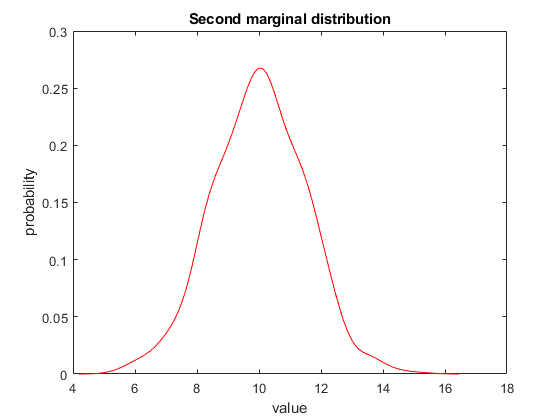

figure;
%plot marginal distribution of seconde (correlated) sample
[f,yi] = ksdensity(y_noised);
plot(yi,f, 'r-');
title('Second marginal distribution');
xlabel('value');
ylabel('probability');

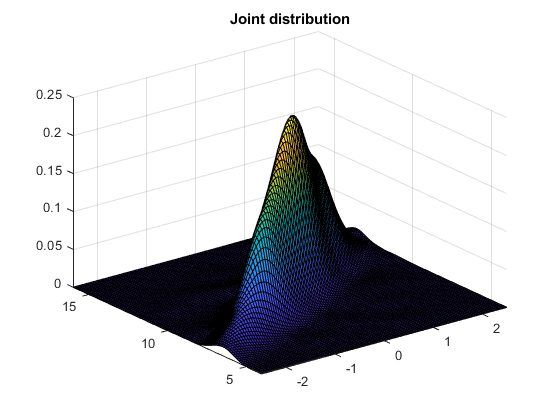

figure;
%plot joint distribution of two samples
gridx1 = -2.5:.05:2.5;
gridx2 = 4:.1:16;
[x1,x2] = meshgrid(gridx1, gridx2);
x1 = x1(:);
x2 = x2(:);
xi = [x1 x2];
X = [x' y_noised'];
ksdensity(X,xi);
title('Joint distribution');